# **Electromagnetism and the Yee Algorithm (PHY5017 Fall 2022)**

# **Project Part 5.2: **

# **Reflection / Transmission**

## **Team Remix: Joe Evans, Maxine Khumalo, Lang Liu**

This code is built-on and modified from research work that J. Evans did in the Fall of 2020.

## Version Comments

This code plots the E field as it reflects and transmits through two media with one interface

## Admin

clearvars
sympref('FloatingPointOutput',true);

## Section 1: Define Constants and Courant Number

### Given Constants

e0 = 8.86e-12;                     %permittivity of free space (F/m)

mu0 = 4e-7 .* pi;                  %permeability of free space (H/m)


er = 1;     %permittivity in medium (set to 1 for free space)


mur = 1;    %permeability in medium (set to 1 for free space)

e = er .* e0;                      %e = epsilon (Units F/m)

mu = mur .* mu0;                   %(Units: H/m)

c = 1./(sqrt(e0*mu0));             %speed of light

### Set Courant number (S)

Set $S=\frac{c \Delta t}{\Delta z}$

Then $\Delta t = S\frac{\Delta z}{c}$

S = 1;   %Courant Number of 1 corresponds to the magic time step

c = 3e8;                        %speed of light in (meters / second)

dz = 5e-3;                      %space increment in meters as defined in the project part 3 parameters

dt = S .* (dz./c) ;             %time increment


## Section 2: Set up the Wave

### Gaussian Pulse in Time "Wave Packet"

sigma = 8 .* dt;                        %as defined in Project Part 3

ts = 20 .* dt;

E0 = 1;

Es = @(t) E0 .* exp(-((t-ts)^2)./(sigma^2));

Z=(dz/2):(dz):1 ;                       %for plotting and video purposes


### Create Matrices to hold wave values



L = 1./dz;               %Number of Space Positions so that z(L) = 1

Tmax = 6 .* sigma;          
T = Tmax ./ dt;          %Number of Time Steps so that over 99% of the Guassian pulse is complete
 

E = zeros(1,L);          %Matrix of electric field values in space (@ t)
Ein = zeros(1,L);        %Temporary Placeholder for the E value input for each space step
Eout = zeros(1,L);       %Temproary placeholder for the E value output for each space step

H = zeros (1,L-1);       %Matrix of magnetic field values in space (@ t)
Hin = zeros(1,L-1);      %Temporary placeholder for the H value input for each space step
Hout = zeros (1,L-1);    %Temporary placeholder for the H value output for each space step

zs = L./4;               %Define the space point of the Gaussian pulse


### Guassian in Space

This is a Guassian in space for the E field, which can be introduced in lieu of a Guassian pulse in time for testing purposes 

 
%   a = 1;                          %height
%   b = 1/4;                        %center
%   d = 8*dz;                       %width
%   f=@(x)a*exp(-((x-b).^2)/(d^2));
%   E(:)=f(Z);
%  


### Square Wave in Space

This is a Square wave in space for the E field, which can be introduced in lieu of a Gaussian pulse in time for testing purposes

% E(50:150)=1;

## Section 3: Setup Video

v=VideoWriter("Part_5.2","MPEG-4");
open(v)
plot(Z,E(:))
xlim([0 1]);
ylim([-1.1 1.1]);
Ylabel="Amplitude";
Xlabel="z";
title='Electric Field: Normal Interface at L/2 '

title = 'Electric Field: Normal Interface at L/2 '

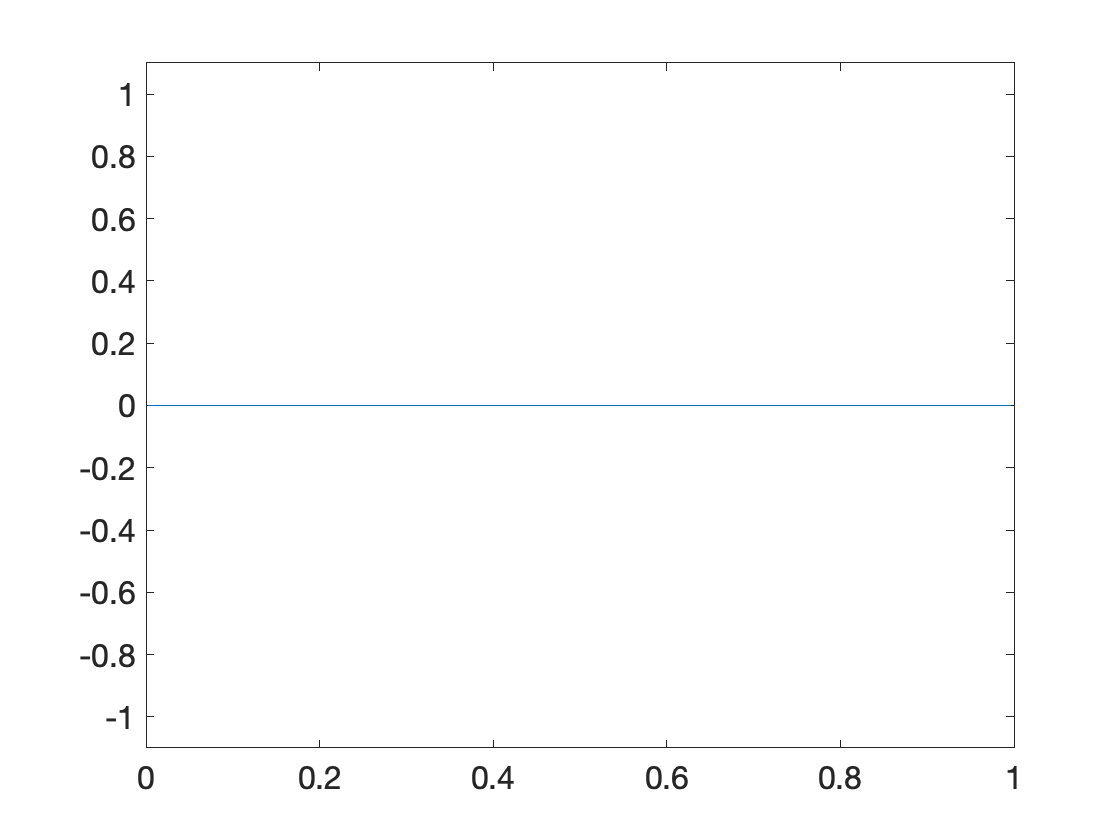

axis manual
set(gca,"nextplot","replacechildren",'fontsize',16)
frame=getframe(gcf);

writeVideo(v,frame)


## Section 4: Propagation, ABCs, and Reflection/Transmission 

Here we place a normal interface at L/2 with $\epsilon_r = 4$. 

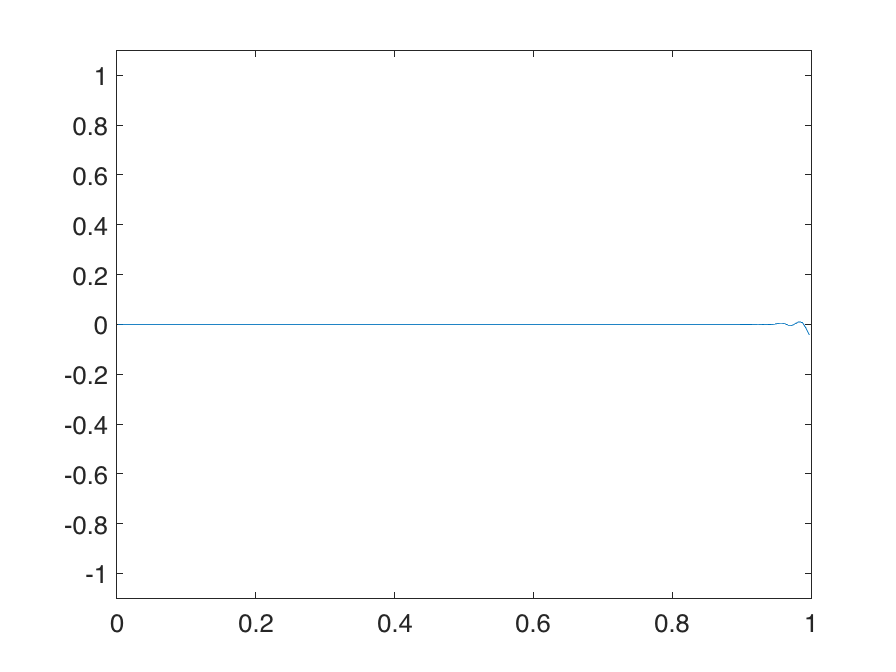


for t=1:6*T                                       %Iterate for T total time steps
    L = round(L);
    
%%%%%%%%%%%%%%%%%%%%% Calculate the E Field %%%%%%%%%%%%%%%%%%%

    

    E2_old = E(2);                                %ABCs
    EM1_old = E(L-1);
    
    for k=2:(L-1)                     
        Hout(k) = H(k);
        Hin(k)= H(k-1);
    end   
    
    for k=2:(L-1)                                  %define interface

        if k<L/2
            er = 1;                                %free space
        else
            er = 4;                                %medium
        end

        E(k) =  E(k) - ( S ./ er )  .* ( Hout(k) - Hin(k) );    %calculate E 
    end
    
    er = 1;                                         %ABCs
    E2_new = E(2);                              
    E(1) = E2_old + (S - sqrt(er*mur)) ./ (S + sqrt(er*mur)) .* (E2_new - E(1));
    
    er=4;
    EM1_new = E(L-1);
    E(L) = EM1_old + (S - sqrt(er*mur)) ./ (S + sqrt(er*mur)) .* (EM1_new - E(L));
    
%%%%%%%%%%%%%%%%%%% Introduce next E pulse Value %%%%%%%%%%%%%%%%%%

    if t<=T
                      
       E(zs) = Es(t*dt);                            %Calculate the next value of the pulse at z = zs 

    end
   
%%%%%%%%%%%%%%%%%% Calculate H Field %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
    for k=1:(L-1)                       
        Eout(k) = E(k+1);
        Ein(k) = E(k);                              %these values are populated with E @ t+(1/2)  
    end
    
    for k=1:(L-1) 
        H(k) = H(k) - (S ./ mur ) .* ( Eout(k) - Ein(k) );      %calculate H
    end
    
%%%%%%%%%%%%%%%%% Plot and Write frame to video %%%%%%%%%%%%%%%%%%%%

    plot(Z,E(:));
    frame=getframe(gcf);
    pause(0.5)
    writeVideo(v,frame)
    
end

close(v)